# Exercise: Multibody

**Author F. Biral**

**date: 22/6/2026**

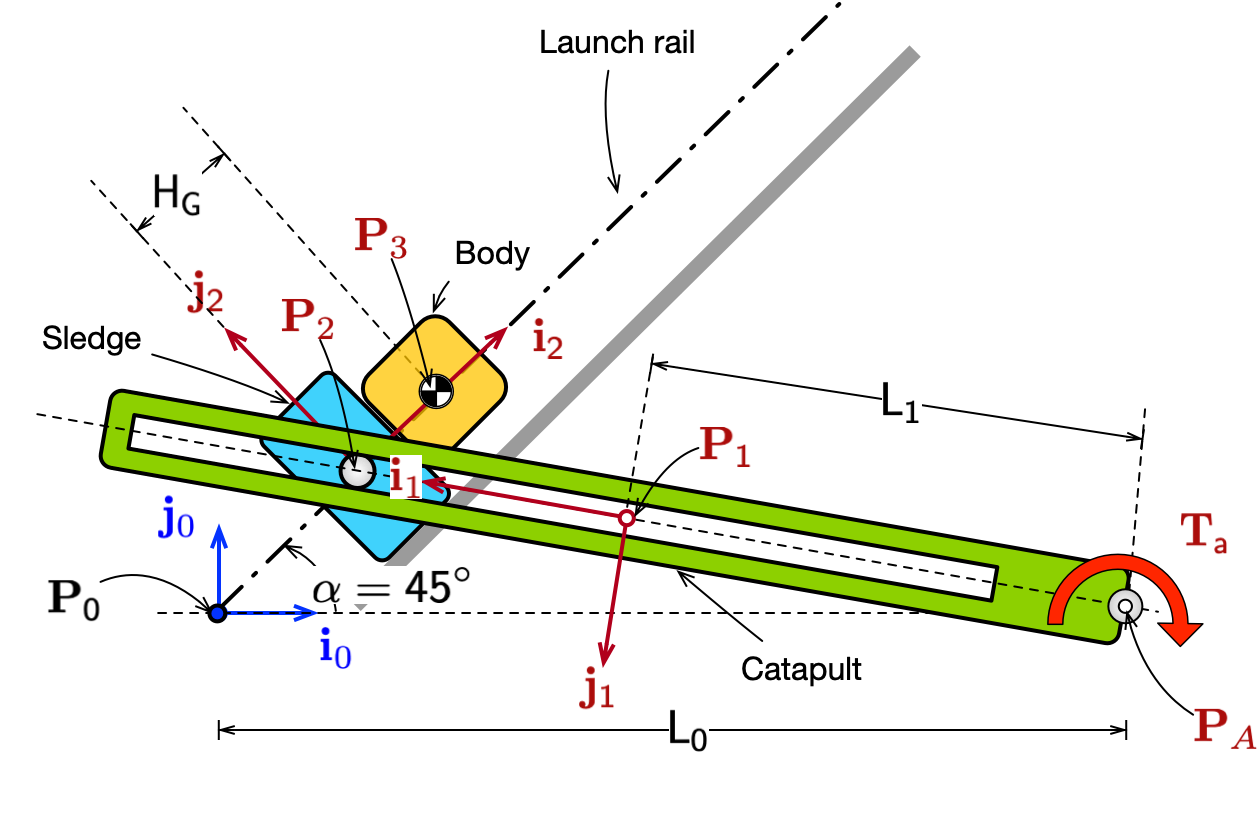

## **List of available command**

There is a collection of functions to ease the process of deriving the equations of kinematics and teh equations of motion. To use it you have to add the path to the folder with: `addpath('MBLibs');`

- `rotate('Z',theta_x(t)): `creates a 4 x 4 transformation matrix with the 3 x3 rotation matrix and origin [0,0,0]

- `rotate3('Z',theta_x(t)): `creates a 3 x 3  rotation matrix 

- `translate([t_x;t_y;t_z]): `creates a 4 x 4 transformation matrix with the 3 x3 identiy matrix and origin [tx,ty,tz]

- `rotate3('Z',theta_x(t)): `creates a 3 x 3 rotation matrix

- `get_unit_vector('X',TM):` returns a 4x1 column vector of the rotation matrix

- `get_unit_vector('X',RM):` returns a 3x1 column vector of the rotation matrix

- `get_rotation_matrix(TM): return` a 3 x 3 rotation matrix 

- `get_origin(TM): `return the 4 x 1 vector of the TM transformation matrix

- `skew_matrix(v): `return the skew matrix given a vector `v` 1x3 

- `inv_frame(TM):`  make the inverse of a 4 x 4 Transformation Matrix

- `inv_rot_mat(RM): `make the transpose of a 3 x 3 rotation matrix

clear all 
close all
clc

addpath('MBLibs');

## Linear Graph and Normal tree

The Linear Graph and the normal tree is in this picture. It is the overall LG with also the external forces.

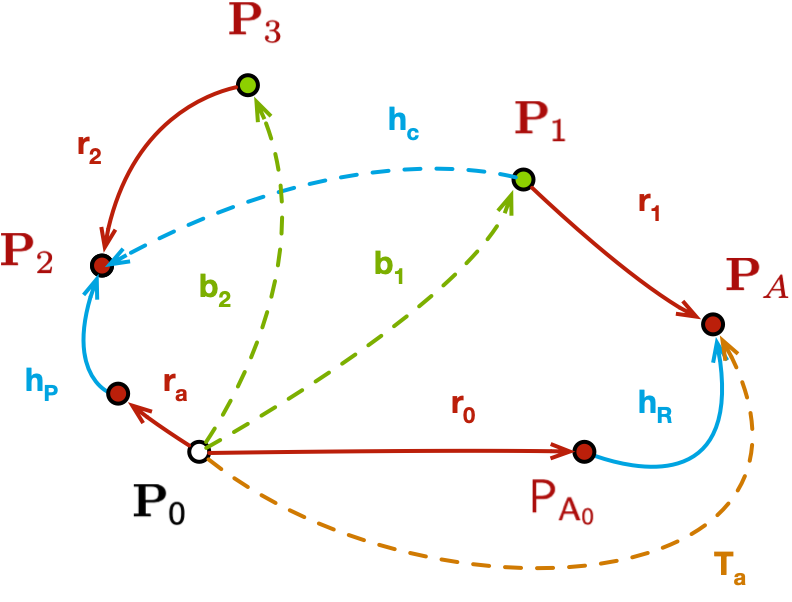

In this case the arm link $r_0$ because it involves a rotation in the absolute frame of an angle $\alpha$.

Below you can see the reaction space of all joints with the corresponding Reaction forces and torque.

**The reaction forces of the joints are in the direction of the eliminated relative degrees of freedom by the joint. Those direction are also called ****Reaction space****. This is also the reason to project the loop of the cut joint in the reaction space.**

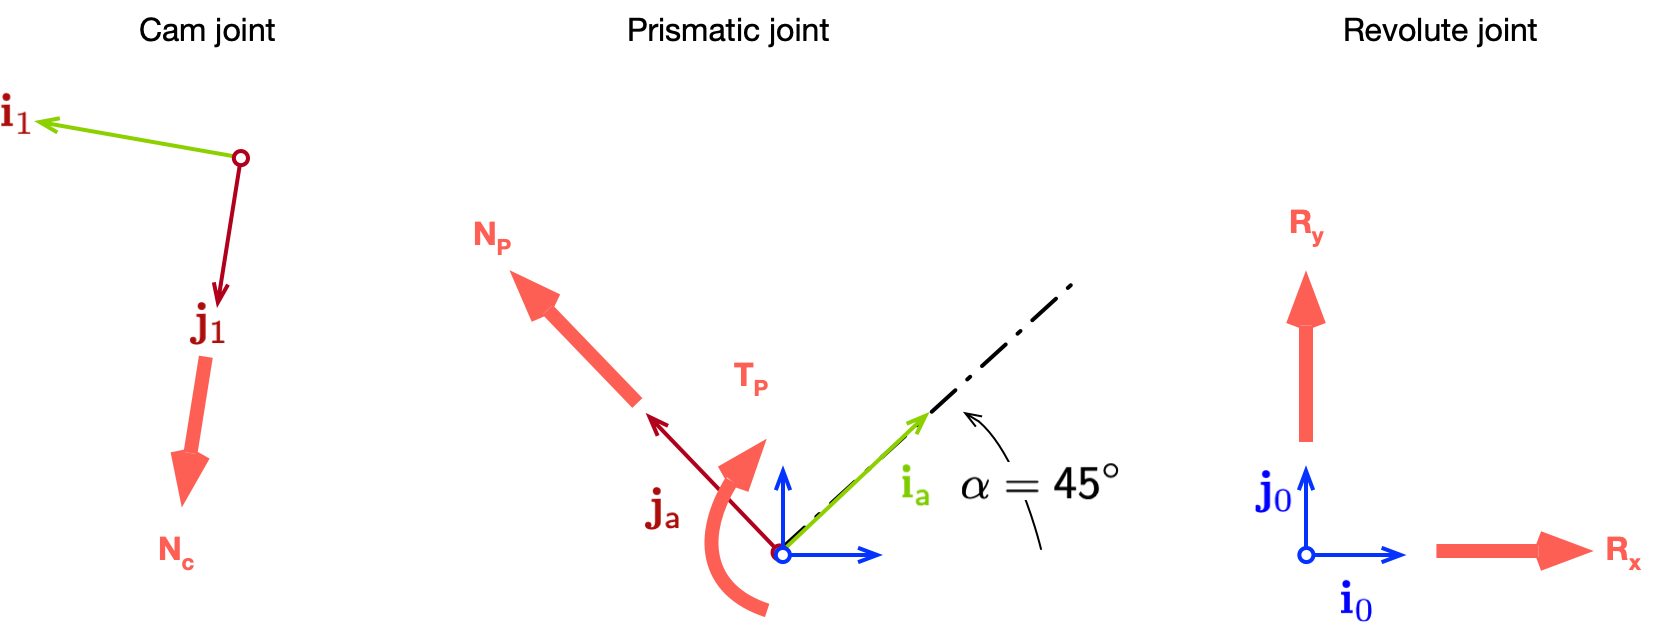

## Multibody system data and definition

syms t theta1(t) theta2(t) s_p(t) s_c(t)
syms x1(t) y1(t) x2(t) y2(t)

% Parameters
syms alpha L_0 L_1 H_G

## Equations of kinematics 

### Kinematic constitutive equations of bodies and arm links

In term of kinematics:

- Constitutive equations of **bodies** means to define the rotation matrices of body frame with absolute angles and vector between body ference frame origin and ground frame origin in absolute coordinates.

- Constitutive equations of** arm links** means to define the auxliary reference frame (vector plus, if any, rotation matrix) between the body frame and the auxiliary frame. Then they must be transformed into absolute coordinates using the body rotation matrix

**Body 1**

% Rotation matrix of body frame 1 
R1 = rotate3('Z',theta1(t))

$$R1 = \left(\begin{array}{ccc} \cos\left(\theta_{1}\left(t\right)\right) & -\sin\left(\theta_{1}\left(t\right)\right) & 0\\ \sin\left(\theta_{1}\left(t\right)\right) & \cos\left(\theta_{1}\left(t\right)\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

% unit vector of sliding axis of cam joint
i1 = get_unit_vector3('X',R1)

$$i1 = \left(\begin{array}{c} \cos\left(\theta_{1}\left(t\right)\right)\\ \sin\left(\theta_{1}\left(t\right)\right)\\ 0 \end{array}\right)$$

j1 = get_unit_vector3('Y',R1) % reaction space of cam joint

$$j1 = \left(\begin{array}{c} -\sin\left(\theta_{1}\left(t\right)\right)\\ \cos\left(\theta_{1}\left(t\right)\right)\\ 0 \end{array}\right)$$


% vector of position of origin body 1 w.r.t. ground origin: absolute coordinates
b1 = [x1(t);y1(t);0];

**Body 2**

% Rotation matrix of body frame 2 
 R2 = rotate3('Z',theta2(t))

$$R2 = \left(\begin{array}{ccc} \cos\left(\theta_{2}\left(t\right)\right) & -\sin\left(\theta_{2}\left(t\right)\right) & 0\\ \sin\left(\theta_{2}\left(t\right)\right) & \cos\left(\theta_{2}\left(t\right)\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

% vector of position of origin body 1 w.r.t. ground origin: absolute coordinates
 b2 = [x2(t);y2(t);0];

**Arm links on ground**

% Arm links on ground
r0 = [L_0;0;0];
ra = [0;0;0];
% 
R0 = rotate3('Z',alpha);
% unit vector of sliding axis: it defines the motion space of the joint
ia = get_unit_vector3('X',R0)

$$ia = \left(\begin{array}{c} \cos\left(\alpha \right)\\ \sin\left(\alpha \right)\\ 0 \end{array}\right)$$

% unit vector orthogonal to sliding axis: it defines the reaction space of
% the joint
ja = get_unit_vector3('Y',R0);

**Arm links of body 1**

r1 = R1*[-L_1;0;0];


**Arm links of body 2**

r2 = R2*[-H_G;0;0];

### Kinematic constitutive equations of joints

The constitutive equations of the joints in term of kinematics can be either:

- the allowed relative translations and rotations (i.e. vector and rotation matrix) 

- or the condtions that imposes the relative motion restriction

**Revolute joint**

The translational vector that defines the relative motion which is  allowed by the revolute jojnt. Thus is a zero components vector since the revolote joint does not allow the relative translation between the two origins of two frames connected by the joint

% translational constitutive equation of rev. joint
hR = [0;0;0];

**Prismatic joint**

The translational vector that defines the relative motion which is  allowed by the primstaic jojnt. Thus is a  vector with a displacement s(t) along the sliding axis since the prismatic joint allows  a relative  translation between the two origins of two frames connected by the joint

% translational constitutive equation of prismatic. joint
hP = s_p(t)*ia;

**Cam joint**

The joint has a relative translation along $j_a$  (y(t)) and a rotation around the z-axis. Instead in does not allow the relative translation along  axis $i_a$ . However, we will project the constrant equation  into the reaction space of the jojnt in order to not involve the coordinate y(t).

syms y(t) % it is defined but not used
% translational constitutive equation of rev. joint: it has a traslation
% along ja and a rotation around Z-axis.
hC = s_c(t)*i1

$$hC = \left(\begin{array}{c} \cos\left(\theta_{1}\left(t\right)\right)\,s_{c}\left(t\right)\\ \sin\left(\theta_{1}\left(t\right)\right)\,s_{c}\left(t\right)\\ 0 \end{array}\right)$$

Normaly we shold also write the rotation matrices of the joints, but it is not necessary 

### Loop equations: constraint equations

### R-Graph

The rotational graph in 2D is the sum of the rotation around the kinematic chain

One option is to use the same tree of the T-graph however this will introduce the angle theta3(t)

Phi_theta2 = theta2(t) == alpha

$$Phi\_theta2 = \theta_{2}\left(t\right)=\alpha$$

### T-Graph

The transaltional grah in 2D is the sum of the translational vector (edges) around the loop. There is only a loop and we cut the cam joint. Formally one can also write the vetcorial loop equal to zero.

Then we have to **project** the loop **in the reaction space of the cut joint**, thus the space of restrained relative motion

**Cam joint vector**

%eq_cut = h3 == r0+h2+r3-(r1+h1)
eq_cut = hC - ( r0+hR-r1-(ra+hP-r2) )  % we write as eq == 0 to allow the projection

$$eq\_cut = \left(\begin{array}{c} \cos\left(\alpha \right)\,s_{p}\left(t\right)-L_{0}+\cos\left(\theta_{1}\left(t\right)\right)\,s_{c}\left(t\right)+H_{G}\,\cos\left(\theta_{2}\left(t\right)\right)-L_{1}\,\cos\left(\theta_{1}\left(t\right)\right)\\ H_{G}\,\sin\left(\theta_{2}\left(t\right)\right)-L_{1}\,\sin\left(\theta_{1}\left(t\right)\right)+\sin\left(\alpha \right)\,s_{p}\left(t\right)+\sin\left(\theta_{1}\left(t\right)\right)\,s_{c}\left(t\right)\\ 0 \end{array}\right)$$

The translational loop vector of the joint must be projected into the reaction space of the join

Phi = simplify(expand(eq_cut.'*j1))

$$Phi = L_{0}\,\sin\left(\theta_{1}\left(t\right)\right)-H_{G}\,\sin\left(\theta_{1}\left(t\right)-\theta_{2}\left(t\right)\right)+\sin\left(\alpha -\theta_{1}\left(t\right)\right)\,s_{p}\left(t\right)$$

% we substitute the theta2(t) angle
Phi = subs( Phi,lhs(Phi_theta2),rhs(Phi_theta2))

$$Phi = L_{0}\,\sin\left(\theta_{1}\left(t\right)\right)+H_{G}\,\sin\left(\alpha -\theta_{1}\left(t\right)\right)+\sin\left(\alpha -\theta_{1}\left(t\right)\right)\,s_{p}\left(t\right)$$

We can also find the analytical solution for s_p(t)

syms y 
tmp = subs( Phi, s_p(t), y);
sol_sp = solve(tmp,y)

$$sol\_sp = -\frac{L_{0}\,\sin\left(\theta_{1}\left(t\right)\right)+H_{G}\,\sin\left(\alpha -\theta_{1}\left(t\right)\right)}{\sin\left(\alpha -\theta_{1}\left(t\right)\right)}$$

If it is not possible to solve it analytically it will be added to the DAE system of equations of dynamics

**Centre of Masses Kinematics**

CoM body 1

% Position velocity and acceleration
G1 = subs( r0+hR-r1,lhs(Phi_theta2),rhs(Phi_theta2)) % b1

$$G1 = \left(\begin{array}{c} L_{0}+L_{1}\,\cos\left(\theta_{1}\left(t\right)\right)\\ L_{1}\,\sin\left(\theta_{1}\left(t\right)\right)\\ 0 \end{array}\right)$$

VG1 = diff(G1,t);
AG1 = diff(VG1,t); % aG1
% angular velocity
tmp = simplify((R1.')*diff(R1,t)); % skew matrix for angular velocity
ang_vel1 = [tmp(3,2) tmp(1,3) tmp(2,1) ].' % angular velocity vector

$$ang\_vel1 = \left(\begin{array}{c} 0\\ 0\\ \frac{\partial }{\partial t}\theta_{1}\left(t\right) \end{array}\right)$$

CoM body 2

% Position velocity and acceleration
G2 = subs( ra+hP-r2,lhs(Phi_theta2),rhs(Phi_theta2)) % b2

$$G2 = \left(\begin{array}{c} \cos\left(\alpha \right)\,s_{p}\left(t\right)+H_{G}\,\cos\left(\alpha \right)\\ \sin\left(\alpha \right)\,s_{p}\left(t\right)+H_{G}\,\sin\left(\alpha \right)\\ 0 \end{array}\right)$$

VG2 = diff(G2,t);
AG2 = diff(VG2,t);
% angular velocity
tmp = simplify((R2.')*diff(R2,t)); % skew matrix for angular velocity
ang_vel2 = [tmp(3,2) tmp(1,3) tmp(2,1)  ].' % angular velocity vector

$$ang\_vel2 = \left(\begin{array}{c} 0\\ 0\\ \frac{\partial }{\partial t}\theta_{2}\left(t\right) \end{array}\right)$$

Position of P2

P2 = ra+hP

$$P2 = \left(\begin{array}{c} \cos\left(\alpha \right)\,s_{p}\left(t\right)\\ \sin\left(\alpha \right)\,s_{p}\left(t\right)\\ 0 \end{array}\right)$$

Vector between P2 and P1

r3 = ra+hP-(r0+hR-r1)

$$r3 = \left(\begin{array}{c} \cos\left(\alpha \right)\,s_{p}\left(t\right)-L_{0}-L_{1}\,\cos\left(\theta_{1}\left(t\right)\right)\\ \sin\left(\alpha \right)\,s_{p}\left(t\right)-L_{1}\,\sin\left(\theta_{1}\left(t\right)\right)\\ 0 \end{array}\right)$$

## Equations of Dynamics

**NOTE**: Since we do not have to differentiate the forces then we do not add (t) dependency on time. Thus it will be easier to use `solve() `command. Otherwiese we are forced to do a formal substitution of the variable (e.g. x(t) --> y_1 ) as above

### Constitutive equations 

From the point of view of dynamics the constitutive equations are:

- **body**: are the Newton Euler equations. The Newton equations (i.e. translational balance) are defined in ground frame normalyThe Euler equations (i.e. moment balance) are defined in body frame

- **joints**: the constitutive equations of joints from dynamic point of view corresponde to the definition of the reaction forces in the reaction space.

**Bodies**

Newton equations

syms m1 Iz1 Fbx_1 Fby_1 Tbz_1  Fb1 Tb1

**Body 1**

Fb1 and Tb1 which are the total force and moment action on the body will be given by the node equations

% acceleration of centre of mass
Fb1 = [Fbx_1,Fby_1,0].'; % total force on body
Tb1  = [0,0,Tbz_1].';        % total torque on body

j0 = [0;1;0]; % unit vector
% Newton Euler equations for body 1: includes also the weight
eqnN1 = m1*AG1== -Fb1

$$eqnN1 = \left(\begin{array}{c} -m_{1}\,\left(L_{1}\,\sin\left(\theta_{1}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta_{1}\left(t\right)+L_{1}\,\cos\left(\theta_{1}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2}\right)=-{\mathrm{Fbx}}_{1}\\ -m_{1}\,\left(L_{1}\,\sin\left(\theta_{1}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2}-L_{1}\,\cos\left(\theta_{1}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta_{1}\left(t\right)\right)=-{\mathrm{Fby}}_{1}\\ 0=0 \end{array}\right)$$

% Euler equation for body 1: in body frame
eqnE1 = Iz1*diff(ang_vel1,t) ==-Tb1

$$eqnE1 = \left(\begin{array}{c} 0=0\\ 0=0\\ {\mathrm{Iz}}_{1}\,\frac{\partial^{2}}{\partial t^{2}}\theta_{1}\left(t\right)=-{\mathrm{Tbz}}_{1} \end{array}\right)$$

**Body 2**

Fb2 and Tb2 which are the total force and moment action on the body will be given by the node equations

syms Fbx_2 Fby_2 Tbz_2 m2 Iz2 Fb2 Tb2
% acceleration of centre of mass
Fb2 = [Fbx_2,Fby_2,0].'; % total force on body
Tb2 = [0,0,Tbz_2].'; % total torque on body

% Newton Euler equations for body 2
eqnN2 = m2*AG2 == -Fb2

$$eqnN2 = \left(\begin{array}{c} m_{2}\,\cos\left(\alpha \right)\,\frac{\partial^{2}}{\partial t^{2}}s_{p}\left(t\right)=-{\mathrm{Fbx}}_{2}\\ m_{2}\,\sin\left(\alpha \right)\,\frac{\partial^{2}}{\partial t^{2}}s_{p}\left(t\right)=-{\mathrm{Fby}}_{2}\\ 0=0 \end{array}\right)$$

eqnE2 = Iz2*diff(ang_vel2,t) == -Tb2

$$eqnE2 = \left(\begin{array}{c} 0=0\\ 0=0\\ {\mathrm{Iz}}_{2}\,\frac{\partial^{2}}{\partial t^{2}}\theta_{2}\left(t\right)=-{\mathrm{Tbz}}_{2} \end{array}\right)$$

**Joints**

syms Rx Ry  N_p  N_c T_p

Definition of  generalised reaction forces in reaction space.

**NOTE**: they are **defined in the reaction space** but then projected to ground frame and for the moment balance projected into the body if used respectivelly in Newton or Euler equations

Frj  = [Rx Ry 0].';  % defined in reaction space and projected in ground frame
Fpj  = R2*[0 N_p 0 ].'; % defined in reaction space and projected in ground frame
Tpj  = R2*[0 0 T_p ].'; % defined in reaction space and projected in ground frame
Fcj  = R1*[0 N_c 0].';  % defined in reaction space and projected in ground frame 

**External forces**

Definition of external forces

syms t_a g 
W1 = -m1*g*j0; % weight body 1
W2 = -m2*g*j0; % weight body 2
TA = [0 0 t_a].';   % defined in the direction where they act and projected in ground frame

### Node equations

In the node balance (cut-set) we assume positive the forces when the enter into the cut-set (drawn around the body). So if the edges of the graph enter into the cutset the force is taken positive. 

#### Translational balance

Node equations around body 1: we follow the same direction of the edges arrow. If they enter into the cut set is positive , if they exist is negative

eqns_node1_A = +Fb1+Frj-Fcj+W1

$$eqns\_node1\_A = \left(\begin{array}{c} {\mathrm{Fbx}}_{1}+\mathrm{Rx}+N_{c}\,\sin\left(\theta_{1}\left(t\right)\right)\\ {\mathrm{Fby}}_{1}+\mathrm{Ry}-g\,m_{1}-N_{c}\,\cos\left(\theta_{1}\left(t\right)\right)\\ 0 \end{array}\right)$$

sol_Fb1 = solve([eqns_node1_A(1), eqns_node1_A(2)],[Fbx_1 Fby_1])

sol_Fb1 = struct with fields:
    Fbx_1: - Rx - N_c*sin(theta1(t))
    Fby_1: g*m1 - Ry + N_c*cos(theta1(t))


Node equation around body 2

eqns_node2_A = +Fb2+Fpj+Fcj+W2

$$eqns\_node2\_A = \left(\begin{array}{c} {\mathrm{Fbx}}_{2}-N_{c}\,\sin\left(\theta_{1}\left(t\right)\right)-N_{p}\,\sin\left(\theta_{2}\left(t\right)\right)\\ {\mathrm{Fby}}_{2}-g\,m_{2}+N_{c}\,\cos\left(\theta_{1}\left(t\right)\right)+N_{p}\,\cos\left(\theta_{2}\left(t\right)\right)\\ 0 \end{array}\right)$$

sol_Fb2 = solve([eqns_node2_A(1), eqns_node2_A(2)],[Fbx_2 Fby_2])

sol_Fb2 = struct with fields:
    Fbx_2: N_c*sin(theta1(t)) + N_p*sin(theta2(t))
    Fby_2: g*m2 - N_c*cos(theta1(t)) - N_p*cos(theta2(t))


#### Rotational balance

We use the skew matrix to implement the vector product.

% Project compute moment in ground and project in body
eqns_node1_B = simplify(...
  Tb1 ...
 +TA ...
-inv_rot_mat(R1)*(skew_matrix(r3)*Fcj) ...
+inv_rot_mat(R1)*(skew_matrix(r1)*Frj))

$$eqns\_node1\_B = \left(\begin{array}{c} 0\\ 0\\ {\mathrm{Tbz}}_{1}+t_{a}-L_{1}\,\mathrm{Ry}\,\cos\left(\theta_{1}\left(t\right)\right)+L_{1}\,\mathrm{Rx}\,\sin\left(\theta_{1}\left(t\right)\right)+N_{c}\,\sin\left(\theta_{1}\left(t\right)\right)\,\left(L_{1}\,\sin\left(\theta_{1}\left(t\right)\right)-\sin\left(\alpha \right)\,s_{p}\left(t\right)\right)+N_{c}\,\cos\left(\theta_{1}\left(t\right)\right)\,\left(L_{0}-\cos\left(\alpha \right)\,s_{p}\left(t\right)+L_{1}\,\cos\left(\theta_{1}\left(t\right)\right)\right) \end{array}\right)$$

sol_Tb1 = solve(eqns_node1_B(3),Tbz_1)

$$sol\_Tb1 = L_{1}\,\mathrm{Ry}\,\cos\left(\theta_{1}\left(t\right)\right)-t_{a}-L_{1}\,\mathrm{Rx}\,\sin\left(\theta_{1}\left(t\right)\right)-N_{c}\,\sin\left(\theta_{1}\left(t\right)\right)\,\left(L_{1}\,\sin\left(\theta_{1}\left(t\right)\right)-\sin\left(\alpha \right)\,s_{p}\left(t\right)\right)-N_{c}\,\cos\left(\theta_{1}\left(t\right)\right)\,\left(L_{0}-\cos\left(\alpha \right)\,s_{p}\left(t\right)+L_{1}\,\cos\left(\theta_{1}\left(t\right)\right)\right)$$

% Project compute moment in ground and project in body
eqns_node2_B = simplify(...
  Tb2 ...
 +Tpj ...
+inv_rot_mat(R2)*(skew_matrix(r2)*Fcj) ...
+inv_rot_mat(R2)*(skew_matrix(r2)*Fpj))

$$eqns\_node2\_B = \left(\begin{array}{c} 0\\ 0\\ T_{p}+{\mathrm{Tbz}}_{2}-H_{G}\,N_{p}-H_{G}\,N_{c}\,\cos\left(\theta_{1}\left(t\right)-\theta_{2}\left(t\right)\right) \end{array}\right)$$

sol_Tb2 = solve(eqns_node2_B(3),Tbz_2)

$$sol\_Tb2 = H_{G}\,N_{p}-T_{p}+H_{G}\,N_{c}\,\cos\left(\theta_{1}\left(t\right)-\theta_{2}\left(t\right)\right)$$

### Equations of motion

Asembling the equations and substituting the node equations we get the DAE equations


tmp = [eqnN1(1:2);eqnN2(1:2);eqnE1(3);eqnE2(3)];
tmp = subs(tmp,sol_Fb1);
tmp = subs(tmp,sol_Fb2);
tmp = subs(tmp,Tbz_1,sol_Tb1);
tmp = subs(tmp,Tbz_2,sol_Tb2);

With the constraint algebraic constrains

alg_eqns = [s_p(t) == sol_sp] % ; Phi_theta2]

$$alg\_eqns = s_{p}\left(t\right)=-\frac{L_{0}\,\sin\left(\theta_{1}\left(t\right)\right)+H_{G}\,\sin\left(\alpha -\theta_{1}\left(t\right)\right)}{\sin\left(\alpha -\theta_{1}\left(t\right)\right)}$$

DAEeqns = [tmp;alg_eqns]

$$DAEeqns = \begin{array}{l} \left(\begin{array}{c} -m_{1}\,\left(L_{1}\,\sin\left(\theta_{1}\left(t\right)\right)\,\sigma_{1}+L_{1}\,\cos\left(\theta_{1}\left(t\right)\right)\,\sigma_{5}\right)=\mathrm{Rx}+\sigma_{3}\\ -m_{1}\,\left(L_{1}\,\sin\left(\theta_{1}\left(t\right)\right)\,\sigma_{5}-L_{1}\,\cos\left(\theta_{1}\left(t\right)\right)\,\sigma_{1}\right)=\mathrm{Ry}-g\,m_{1}-\sigma_{4}\\ m_{2}\,\cos\left(\alpha \right)\,\sigma_{6}=-\sigma_{3}-N_{p}\,\sin\left(\theta_{2}\left(t\right)\right)\\ m_{2}\,\sin\left(\alpha \right)\,\sigma_{6}=\sigma_{4}-g\,m_{2}+N_{p}\,\cos\left(\theta_{2}\left(t\right)\right)\\ {\mathrm{Iz}}_{1}\,\sigma_{1}=t_{a}-L_{1}\,\mathrm{Ry}\,\cos\left(\theta_{1}\left(t\right)\right)+L_{1}\,\mathrm{Rx}\,\sin\left(\theta_{1}\left(t\right)\right)+N_{c}\,\sin\left(\theta_{1}\left(t\right)\right)\,\left(L_{1}\,\sin\left(\theta_{1}\left(t\right)\right)-\sin\left(\alpha \right)\,s_{p}\left(t\right)\right)+N_{c}\,\cos\left(\theta_{1}\left(t\right)\right)\,\left(L_{0}-\cos\left(\alpha \right)\,s_{p}\left(t\right)+L_{1}\,\cos\left(\theta_{1}\left(t\right)\right)\right)\\ {\mathrm{Iz}}_{2}\,\frac{\partial^{2}}{\partial t^{2}}\theta_{2}\left(t\right)=T_{p}-H_{G}\,N_{p}-H_{G}\,N_{c}\,\cos\left(\theta_{1}\left(t\right)-\theta_{2}\left(t\right)\right)\\ s_{p}\left(t\right)=-\frac{L_{0}\,\sin\left(\theta_{1}\left(t\right)\right)+H_{G}\,\sigma_{2}}{\sigma_{2}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial^{2}}{\partial t^{2}}\theta_{1}\left(t\right)\\ \sigma_{2}=\sin\left(\alpha -\theta_{1}\left(t\right)\right)\\ \sigma_{3}=N_{c}\,\sin\left(\theta_{1}\left(t\right)\right)\\ \sigma_{4}=N_{c}\,\cos\left(\theta_{1}\left(t\right)\right)\\ \sigma_{5}={\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2}\\ \sigma_{6}=\frac{\partial^{2}}{\partial t^{2}}s_{p}\left(t\right) \end{array}$$

Variable and equations

the torque t_a is known and the unknown reaction joints are

rvars = [Rx Ry  N_p  N_c T_p]

$$rvars = \left(\begin{array}{ccccc} \mathrm{Rx} & \mathrm{Ry} & N_{p} & N_{c} & T_{p} \end{array}\right)$$

xvars = [theta1(t), s_p(t)]

$$xvars = \left(\begin{array}{cc} \theta_{1}\left(t\right) & s_{p}\left(t\right) \end{array}\right)$$


yvars = [xvars rvars ]

$$yvars = \left(\begin{array}{ccccccc} \theta_{1}\left(t\right) & s_{p}\left(t\right) & \mathrm{Rx} & \mathrm{Ry} & N_{p} & N_{c} & T_{p} \end{array}\right)$$

% check the system is consistent
length(yvars) == length(DAEeqns)

ans = logical
   1


syms a1 a2 sp
tmp = subs( DAEeqns,{diff(s_p(t),t,t),diff(theta1(t),t,t),s_p(t)},{a1,a2, sp});

solve(tmp,[a1,a2, sp, rvars])

ans = struct with fields:
     a1: (Iz2*cos(theta1(t))*sin(theta2(t))*diff(theta2(t), t, t) - Iz2*cos(theta2(t))*sin(theta1(t))*diff(theta2(t), t, t) - H_G*g*m2*sin(theta1(t)) + H_G*g*m2*sin(theta2(t))*cos(theta1(t) - theta2(t)))/(H_G*m2*(cos(theta1(t))*cos(alpha) + sin(theta1(…
     a2: (H_G*t_a*cos(theta1(t))*sin(alpha - theta1(t))*cos(alpha) + H_G*t_a*sin(theta1(t))*sin(alpha - theta1(t))*sin(alpha) + Iz2*L_0*sin(theta1(t))^2*sin(theta2(t))*sin(alpha)^2*diff(theta2(t), t, t) - H_G*t_a*cos(theta2(t))*sin(alpha - theta1(t))*c…
     sp: -(L_0*sin(theta1(t)) + H_G*sin(alpha - theta1(t)))/sin(alpha - theta1(t))
     Rx: -(Iz1*Iz2*cos(theta2(t))*sin(theta1(t))*sin(alpha - theta1(t))*cos(alpha)*diff(theta2(t), t, t) + H_G*L_1^3*m1^2*cos(theta1(t))^4*sin(alpha - theta1(t))*cos(alpha)*diff(theta1(t), t)^2 + Iz1*Iz2*sin(theta1(t))*sin(theta2(t))*sin(alpha - theta1…
     Ry: (Iz1*Iz2*cos(theta1(t))*sin(theta2(t))*sin(alpha - theta1(t))*sin(alpha)*diff(theta2(t), t, t) - H_G*L_1^3*m1^2*sin(thet